## testing

x = linspace(0,2*pi,100)

x =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


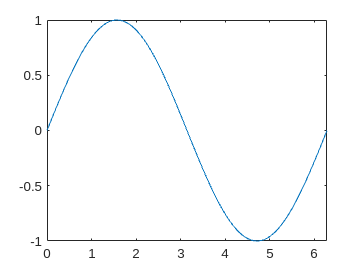

plot(x,sin(x))

## part 1

### Q 1

x = linspace(0, 32,1000)

x =          0    0.0320    0.0641    0.0961    0.1281    0.1602    0.1922    0.2242    0.2563    0.2883    0.3203    0.3524    0.3844    0.4164    0.4484    0.4805    0.5125    0.5445    0.5766    0.6086    0.6406    0.6727    0.7047    0.7367    0.7688    0.8008    0.8328    0.8649    0.8969    0.9289    0.9610    0.9930    1.0250    1.0571    1.0891    1.1211    1.1532    1.1852    1.2172    1.2492    1.2813    1.3133    1.3453    1.3774    1.4094    1.4414    1.4735    1.5055    1.5375    1.5696


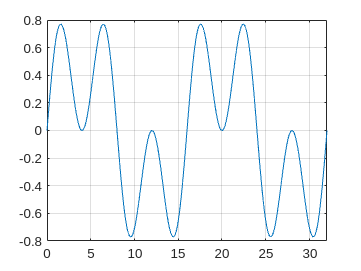

plot(x, sin(pi*x/4).*cos(pi*x/8))
grid on
xlim([0,32])

### Q 2

x = linspace(-10, 10,100)

x =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


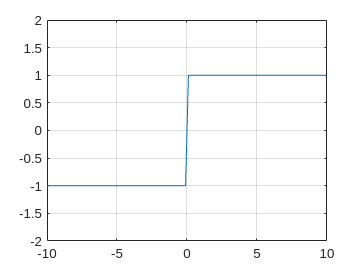

plot(x, sign(x))
grid on
xlim([-10,10])
ylim([-2,2])

### Q 3

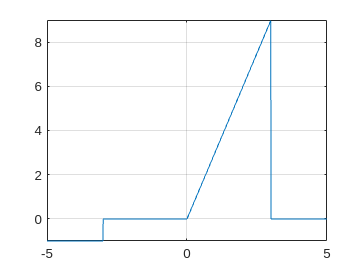

syms x;
y = piecewise(x<-3,-1,-3<x<0,0,0<x<3,3*x,x>3,exp(-2.5*x));
fplot(x,y);
grid on

## part 2

### Q 1


$$a_0 =\frac{\;1}{2L}\int_{-L}^L f\left(x\right)\mathrm{dx}$$



$$a_n =\frac{\;1}{L}\int_{-L}^L \;f\left(x\right)\cos \left(\frac{\;n\pi }{L}x\right)\mathrm{dx}$$



$$b_n =\frac{\;1}{L}\int_{-L}^L \;f\left(x\right)\sin \left(\frac{\;n\pi }{L}x\right)\mathrm{dx}$$



$$f\left(x\right)=a_0 +\sum_{n=1}^{\infty } \;a_n \cos \left(\frac{\;n\pi }{L}x\right)+b_n \sin \left(\frac{\;n\pi }{L}x\right)$$


function [f, fshow] = fs_cal(N, P, alpha, Nshow)
    syms x
    L = P / 2;

    f_sym = x^alpha;

    a_0 = 1 / (2 * L) * int(f_sym, -L, L);
    f = a_0;
    fshow = a_0;

    for n = 1:N
        a_n = 1 / L * int(f_sym * cos(n * pi / L * x), -L, L);
        b_n = 1 / L * int(f_sym * sin(n * pi / L * x), -L, L);

        f = f + a_n * cos(n * pi / L * x) + b_n * sin(n * pi / L * x);

        if n == Nshow
            fshow = f;
        end
    end
end

Let's try

N = 7

N = 7

P = 5

P = 5

alpha = 3

alpha = 3

Nshow = 5

Nshow = 5


[f, fshow] = fs_cal(N,P,alpha,Nshow);

f = matlabFunction(f);
disp(fshow)

$$\frac{125\,\sin\left(\frac{6\,\pi \,x}{5}\right)\,\left(3\,\pi^{2}-2\right)}{36\,\pi^{3}}-\frac{125\,\sin\left(\frac{4\,\pi \,x}{5}\right)\,\left(2\,\pi^{2}-3\right)}{16\,\pi^{3}}-\frac{125\,\sin\left(\frac{8\,\pi \,x}{5}\right)\,\left(8\,\pi^{2}-3\right)}{128\,\pi^{3}}+\frac{\sin\left(2\,\pi \,x\right)\,\left(25\,\pi^{2}-6\right)}{4\,\pi^{3}}+\frac{125\,\sin\left(\frac{2\,\pi \,x}{5}\right)\,\left(\pi^{2}-6\right)}{4\,\pi^{3}}$$

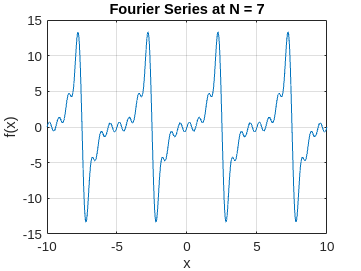


x = linspace(-2*P, 2*P, 1000);

plot(x, f(x));
title(['Fourier Series at N = ', num2str(N)]);
xlabel('x');
ylabel('f(x)');
grid on;

### Q 2

function [f, fshow] = fs_cal_ln(N,P,alpha, beta, Nshow)
    syms x
    L = P / 2;

    f_sym = log(alpha * x) * (x ^ beta);

    a_0 = 1 / (2 * L) * int(f_sym, -L, L);
    f = a_0;
    fshow = a_0;

    for n = 1:N
        a_n = 1 / L * int(f_sym * cos(n * pi / L * x), -L, L);
        b_n = 1 / L * int(f_sym * sin(n * pi / L * x), -L, L);

        f = f + a_n * cos(n * pi / L * x) + b_n * sin(n * pi / L * x);

        if n == Nshow
            fshow = f;
        end
    end
end

Let's try

P_q2 = 6

P_q2 = 6

alpha_q2 = 2

alpha_q2 = 2

beta_q2 = 3

beta_q2 = 3


[f, fshow] = fs_cal_ln(10,P_q2,alpha_q2,beta_q2,5);

disp(fshow);

$$\begin{array}{l} \frac{\cos\left(\pi \,x\right)\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\cos\left(\pi \,x\right)\mathrm{d}x}{3}+\frac{\sigma_{2}\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\sigma_{2}\mathrm{d}x}{3}+\frac{\cos\left(\sigma_{5}\right)\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\cos\left(\sigma_{5}\right)\mathrm{d}x}{3}+\frac{\cos\left(\sigma_{4}\right)\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\cos\left(\sigma_{4}\right)\mathrm{d}x}{3}+\frac{\cos\left(\sigma_{3}\right)\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\cos\left(\sigma_{3}\right)\mathrm{d}x}{3}+\frac{\sin\left(\pi \,x\right)\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\sin\left(\pi \,x\right)\mathrm{d}x}{3}+\frac{\sigma_{1}\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\sigma_{1}\mathrm{d}x}{3}+\frac{\sin\left(\sigma_{5}\right)\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\sin\left(\sigma_{5}\right)\mathrm{d}x}{3}+\frac{\sin\left(\sigma_{4}\right)\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\sin\left(\sigma_{4}\right)\mathrm{d}x}{3}+\frac{\sin\left(\sigma_{3}\right)\,\int_{-3}^{3}x^{3}\,\log\left(2\,x\right)\,\sin\left(\sigma_{3}\right)\mathrm{d}x}{3}-\frac{27\,\pi \,\mathrm{i}}{8}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,x}{3}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,x}{3}\right)\\ \sigma_{3}=\frac{5\,\pi \,x}{3}\\ \sigma_{4}=\frac{4\,\pi \,x}{3}\\ \sigma_{5}=\frac{2\,\pi \,x}{3} \end{array}$$

### Q 3

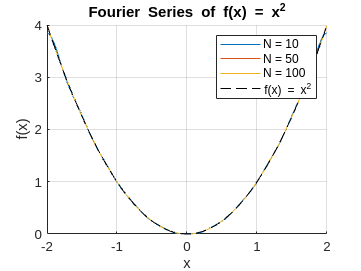

P_q3 = 4;

N_values = [10, 50, 100];

x_vals = linspace(-P_q3/2, P_q3/2, 1000);

figure;
hold on;

for N = N_values
    [f, ~] = fs_cal(N, P_q3, 2, 1);
    f_func = matlabFunction(f);

    plot(x_vals, f_func(x_vals), 'DisplayName', ['N = ', num2str(N)]);
end

plot(x_vals, x_vals.^2, 'k--', 'DisplayName', 'f(x) = x^2');

title('Fourier Series of f(x) = x^2');
xlabel('x');
ylabel('f(x)');
xlim([-P_q3/2, P_q3/2]);
grid on;
legend show;
hold off;

### Q 4


$$a_0 =\frac{\;1}{2\pi }\int_{-\pi }^{\pi } x^2 \mathrm{dx}=\frac{\;1}{6\pi }\times 2\pi^3 =\frac{\pi^2 }{3}$$



$$a_n =\frac{\;1}{\pi }\int_{-\pi }^{\pi } \;x^2 \cos \left(\mathrm{nx}\right)\mathrm{dx}=$$

$$\frac{\left(n^2x^2-2\right)\sin\left(nx\right)+2nx\cos\left(nx\right)}{{\pi}n^3} \big|_{-\pi}^\pi=\frac{2\left(\overbrace{\left({\pi}^2n^2-2\right)\sin\left({\pi}n\right)}^{0}+2{\pi}n\cos\left({\pi}n\right)\right)}{{\pi}n^3}$$



$$=\frac{4}{n^2}\overbrace{\cos\left({\pi}n\right)}^{(-1)^n}=\frac{4(-1)^n}{n^2$$



$$b_n =0\left(\mathrm{even}\right)$$



$$\Longrightarrow f\left(x\right)=\frac{\pi^2 }{3}+4\sum_{n=1}^{\infty } \frac{{\left(-1\right)}^n }{n^2 }\cos \left(\mathrm{nx}\right)$$



$$x=\pi \Longrightarrow \frac{\;1}{2}\left(\pi^2 +{\left(-\pi \right)}^2 \right)=\frac{\pi^2 }{3}+4\sum_{n=1}^{\infty } \frac{{\left(-1\right)}^n }{n^2 }\cos \left(n\pi \right)=\frac{\pi^2 }{3}+4\sum_{n=1}^{\infty } \frac{{\left(-1\right)}^n }{n^2 }{\left(-1\right)}^n =\frac{\pi^2 }{3}+4\sum_{n=1}^{\infty } \frac{1}{n^2 }$$



$$\Longrightarrow \sum_{n=1}^{\infty } \frac{1}{n^2 }=\frac{\;1}{4}\times \left(\pi^2 -\frac{\pi^2 }{3}\right)=\frac{\pi^2 }{6}\simeq 1\ldotp 644$$


N = 10;
P = 2*pi;
alpha = 2;
Nshow = 1;

[f, ~] = fs_cal(N,P,alpha,Nshow);
f_func = matlabFunction(f);
f_func(pi)

ans = 9.4889

TODO:mips??

### Q5

function f = harmonic_cal(x,y,N)
    syms t;
    A_0 = 2*sum(y)/length(x);
    f = A_0 / 2;

    for n = 1:N
        A_n = 2*sum(y.*cos(n*x)) / n;
        B_n = 2*sum(y.*sin(n*x)) / n;
        f = f + A_n * cos(n*t) + B_n * sin(n*t);
    end
end

x = [0 , pi/3, 2*pi/3 , pi , 4*pi/3 , 5*pi/3 , 2*pi];
y = [1 , 1.4 , 1.9 , 1.7 , 1.5 , 1.2 , 1];

f = harmonic_cal(x,y,3);
disp(vpa(f,4))

$$0.7\,\cos\left(2.0\,t\right)-0.1732\,\sin\left(2.0\,t\right)+0.7333\,\cos\left(3.0\,t\right)-2.694e-16\,\sin\left(3.0\,t\right)-0.2\,\cos\left(t\right)+1.039\,\sin\left(t\right)+1.386$$

## part 3

### Q 2

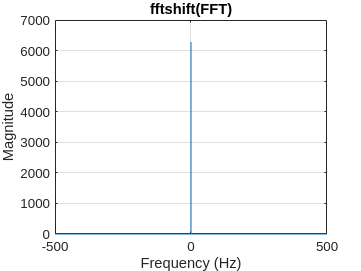

f = @(t) cos(t);

fs = 1000;
t = 0:1/fs:4*pi;

y = f(t);

Y = fft(y);

Y_shifted = fftshift(Y);
f_axis = linspace(-fs/2, fs/2, length(Y));

plot(f_axis, abs(Y_shifted));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('fftshift(FFT)');
grid on;

for f(t)=1

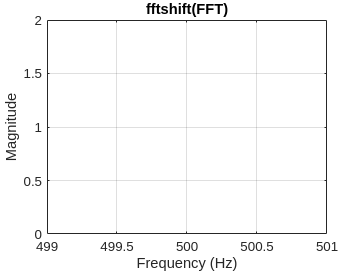

f = @(t) 1;

fs = 1000;
t = 0:1/fs:4*pi;

y = f(t);

Y = fft(y);

Y_shifted = fftshift(Y);
f_axis = linspace(-fs/2, fs/2, length(Y));

plot(f_axis, abs(Y_shifted));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('fftshift(FFT)');
grid on;

for f(t)=‫‪δ‬‬(t)

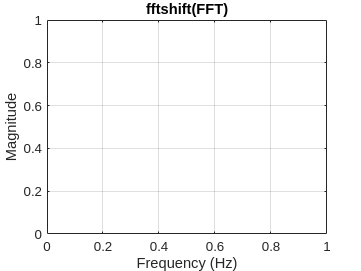

f = @(t) dirac(t);

fs = 1000;
t = 0:1/fs:4*pi;

y = f(t);

Y = fft(y);

Y_shifted = fftshift(Y);
f_axis = linspace(-fs/2, fs/2, length(Y));

plot(f_axis, abs(Y_shifted));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('fftshift(FFT)');
grid on;

TODO: write handwrite

### Q3

[audioData, Fs] = audioread('/home/mvajhi/code/Eng_math/ca1/ABITW.mp3');
sound(audioData, Fs);
Fs

Fs = 44100

فرکانس نمونه‌برداری به تعداد نمونه‌هایی که در هر ثانیه از سیگنال صوتی گرفته می‌شود، اشاره دارد. هرچه فرکانس نمونه‌برداری بیشتر باشد، کیفیت صدای ضبط شده بهتر خواهد بود.

انتخاب فرکانس نمونه‌برداری مناسب برای یک سیگنال صوتی، به حداکثر فرکانس موجود در آن سیگنال بستگی دارد. طبق قضیه نایکوئیست، برای بازسازی دقیق یک سیگنال صوتی از روی نمونه‌های دیجیتال آن، فرکانس نمونه‌برداری باید حداقل دو برابر حداکثر فرکانس موجود در سیگنال باشد.

 حداکثر فرکانس قابل شنیدن انسان حدود 20 کیلوهرتز است. به همین دلیل، فرکانس نمونه‌برداری 44100 هرتز که در بسیاری از فایل‌های صوتی استفاده می‌شود، برای بازسازی دقیق این صداها کافی است.

audiowrite("/home/mvajhi/code/Eng_math/ca1/ABITW_Fs_doubled.wav",audioData,Fs*2);
audiowrite("/home/mvajhi/code/Eng_math/ca1/ABITW_Fs_halved.wav",audioData,Fs/2);

When we doubled the frequency, the time of the audio file was halved and its speed doubled, and the opposite happened when the frequencies were halved